Fundamentos de control                                                                                                                                                                                                       

# Introducción a MATLAB

## Matrices y vectores

MATLAB fue inicialmente diseñado como una herramienta para facilitar el cálculo matricial, de hecho el nombre MATLAB deriva de “MATrix LABoratory” (Laboratorio de Matrices).

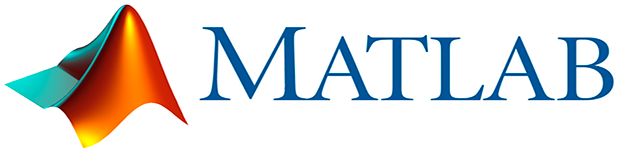

Hoy día, MATLAB es un sistema interactivo y un lenguaje de programación de carácter científico y técnico que es utilizado, con éxito, tanto en el ámbito académico como en el ámbito industrial.

Las características principales de MATLAB son:

- Orientado al cálculo matemático y científico.

- Uso de las matrices como elemento básico.

- Potencia de representación gráfica.

- Sistema abierto.

- Facilidad de uso.

- Lenguaje de programación.

- Aplicable a multitud de campos (versátil).

## `1. El entorno MATLAB`

La ventana de MATLAB se encuentra dividida en cuatro partes fundamentales (subventanas) que inicialmente muestran la siguiente información:

- Subventana izquierda: muestra el conteido del **directorio de trabajo actual** y, en la parte inferior, detalles del fichero que tengamos seleccionado (versión del fichero, autor, etc.).

- Subventana central-arriba: contiene el** editor de código** (ficheros con extensión *.m*) o de scripts vivos (*live scripts*, extensión *.mlx*).

- Subventana central-abajo: **ventana de comandos** (*Command Window*) donde se introducen los comandos propios de MATLAB. Esta ventana tiene capacidad de “memorizar” los comandos que han sido introducidos con anterioridad y consultarlos pulsando la tecla arriba. 

- Subventana superior derecha: es el denominado **espacio de trabajo **(*Workspace*) y en ella aparecen todas las variables que se han utilizado en la ventana de comandos. Esta ventana tiene la capacidad de crear nuevas variables, eliminar variables y de visualizar y editar los valores de las variables existentes.

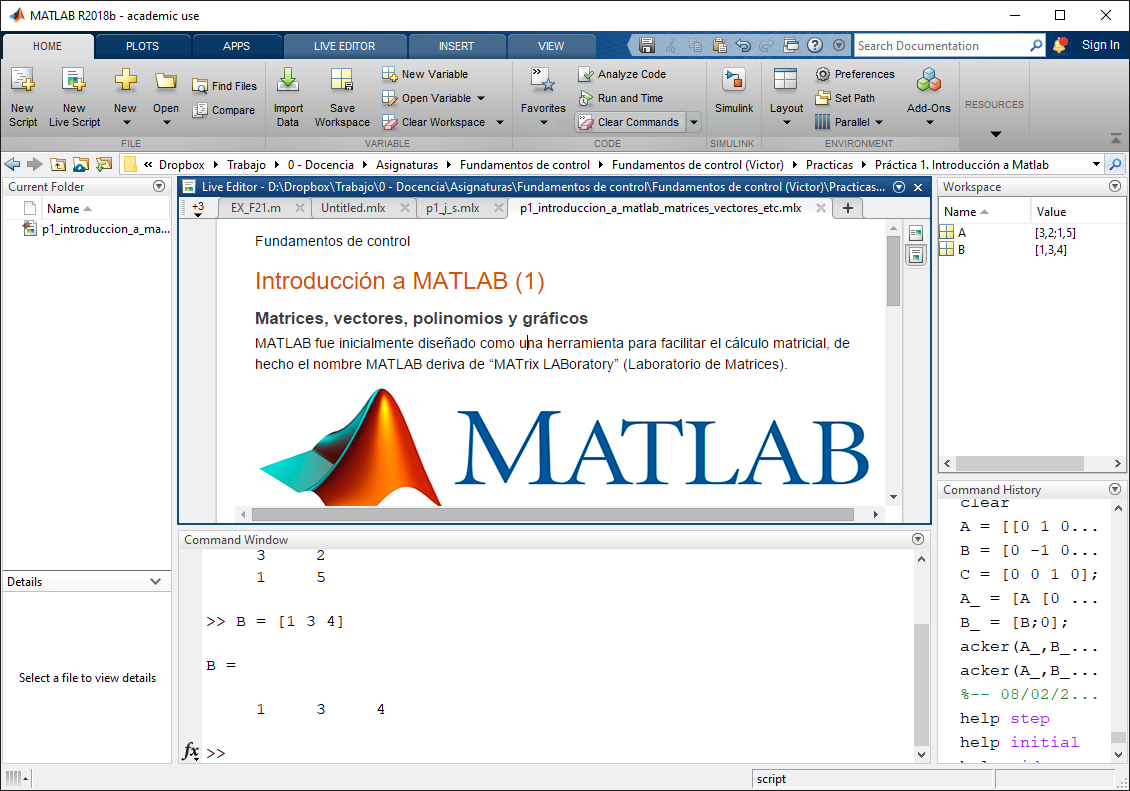

Además, en la parte superior se muestra la ruta del directorio de trabajo actual, la cual puede cambiarse para guardar y ejecutar comandos desde una carpeta definida por el propio usuario.

Una vez nos han presentado el entorno, vamos a empezar a jugar con él. 

***Pista:*** para cambiar esta distribución de ventanas inicial, o mostrar algunas ocultas por defecto (por ejemplo, el historial de comandos, *Command history*), puede emplearse la opción *Layout* dentro del menú *Home*.

## `2. Matrices y vectores`

El elemento básico o primitiva de trabajo de MATLAB son las **matrices**. Para MATLAB, por defecto, cualquier variable es considerada como una matriz rectangular, y esta no necesita ser dimensionada previamente para ser usada. La mayoría de las funciones de MATLAB están diseñadas para operar directamente con matrices.

Los elementos de una matriz pueden ser números enteros, reales, complejos, o expresiones matemáticas, entre otras muchas cosas. 

### `2.1 Definición de matrices`

Las matrices en MATLAB pueden ser creadas de diversas formas, pero la más común es emplear una lista explicita de elementos. Por ejemplo:

***Pista:*** si una operación de asignación (=) no incluye un punto y coma al final (;), MATLAB mostrará el contenido de la variable asignada tras ejecutarla.Si lo incluye, a esto se le denomina modo *no echo*.

Esta creación tiene varios aspectos a destacar:

- La matriz se denomina `A`,

- se incluye un símbolo de asignación `=`,

- la definición de la matriz comienza con un corchete `[`,

- cada columna se separa por una coma `,`, 

- cada fila se separa empleando un punto y coma `;`, y

- la definición de la matriz finaliza con un corchete `]`.

MATLAB utiliza la notación matemática para referenciar un elemento de una matriz. Es decir, para referenciar el elemento de la fila` i` y la columna` j` de la matriz` A` se usaría la expresión `A(i,j)`.

**Tarea 1:** Crea la matriz `A` tal que:


$$A=\left\lbrack \begin{array}{cccc}
-1 & 2 & 3 & -4\\
5 & 6 & -7 & 8\\
9 & -10 & 11 & 12\\
13 & -14 & -15 & 16
\end{array}\right\rbrack$$


y consulta su elemento en la fila 2 y columna 3.

% Tu código aquí, para ejecutarlo puedes pulsar el botón Run o usar la
% combinación de teclas Ctrl+Enter
A = [-1 2 3 -4;5 6 -7 8;9 -10 11 12;13 -14 -15 16]

A =     -1     2     3    -4
     5     6    -7     8
     9   -10    11    12
    13   -14   -15    16


elemnt = A(2,3)

elemnt = -7

**Tarea 2:** Crea la matriz B tal que:


$$B=\left\lbrack \begin{array}{cc}
1+i & 2+2i\\
3+3i & 4+4i
\end{array}\right\rbrack$$


y consulta su elemento en la fila 2 y columna 1.

***Pista:*** En MATLAB la unidad imaginaria básica puede representarse empleando `i` o `j` indistintamente.

% Tu código aquí
B = [1+i 2+2*i;3+3*i 4+4*i]

B =    1.0000 + 1.0000i   2.0000 + 2.0000i
   3.0000 + 3.0000i   4.0000 + 4.0000i


element = B(2,1)

element = 3.0000 + 3.0000i

#### `Matrices de uso frecuente`

MATLAB incorpora una serie de comandos para crear matrices de uso frecuente. En las siguientes celdas de código puedes jugar con ellas. Fijaté en los parámetros de entrada:

% Matriz de ceros de dimensión 2x2
M = zeros(2)

M =      0     0
     0     0


% Matriz de ceros de dimensión 2x3
M = zeros(2,3)

M =      0     0     0
     0     0     0


% Matriz de unos (identidad) de dimensión 3x3
M = eye(3)

M =      1     0     0
     0     1     0
     0     0     1


% Matriz de números aleatorios (distribución uniforme)
M = rand(3)

M =     0.8147    0.9134    0.2785
    0.9058    0.6324    0.5469
    0.1270    0.0975    0.9575


% Matriz de números aleatorios (distribución normal)
M = randn(3)

M =     2.7694    0.7254   -0.2050
   -1.3499   -0.0631   -0.1241
    3.0349    0.7147    1.4897


### `2.2 Definiendo vectores`

Partiendo de la base de que la primitiva de trabajo es la matriz, MATLAB también puede trabajar con **escalares** (matrices 1x1) y con **vectores fila** (matrices 1xn) o **columna** (matrices nx1). 

**Tarea 3:** Crea el vector columna `v` tal que:


$$v=\left\lbrack \begin{array}{c}
1\\
-2\\
3\\
4
\end{array}\right\rbrack$$


% Tu código aquí
v = [1;-2;3;4]

v =      1
    -2
     3
     4


### `2.3 Trabajando con matrices`

#### `Traspuesta de una matriz`

En MATALAB la traspuseta de una matriz se obtiene con el operador tilde `'`. Por ejemplo:

**Tarea 4:** Calcular, a partir de la matriz `A `previamente definida, una nueva matriz `C`, tal que: $C=A^T$

% Tu código aquí
C = A'

C =     -1     5     9    13
     2     6   -10   -14
     3    -7    11   -15
    -4     8    12    16


#### `Aritmétrica de matrices`

Los siguientes comandos implementan operaciones aritmétricas básicas:

- `+`: Suma de matrices.

- `-`: Resta de matrices.

- `*`: Producto de matrices.

- `/`: División matricial por la derecha ($A/B$ equivale a $A\times B^{-1}$) .

- \: División matricial por la izquierda ($A\backslash B$ equivale a $A^{-1} \times B$).

- `^`: Operador potencia.

- `inv`: inversa de una matriz.

- `'`: traspuesta de una matriz.

**Tarea 5:** Calcular, a partir de la matriz `A` y el vector `v `previamente definidos, el producto: $C=A\times v$ . ¿Qué pasaría si intento realizar el producto $C=v\times A$? ¿Por qué?

% Tu código aquí
C = A * v 

C =    -12
     4
   110
    60


%No se puede multiplicar v con A dado que v es 4x1 y A 4x4. Al hacer A*v
%obtenemos (4x4)(4x1) coinciden los cuatros luego nos quedara una matríz
%resultante de 4x1 y se puede multiplicar. Sin embargo al hacerlo al revés
%no nos coincide luego no se pueden multiplicar.

**Tarea 6: **Calcular, a partir de la matriz `A` y el vector `v`, una nuevas matrices `x1` y `x2`, tales que:


$$\left\lbrace \begin{array}{ll}
A*\textrm{x1}=v & \;\\
\textrm{x2}*A=v^{\prime }  & \;
\end{array}\right.$$


% Tu código aquí
x1 = A^-1 * v

x1 =     0.7508
   -0.2222
    0.0303
   -0.5261



x2 = v' * A^-1

x2 =    -0.9091    0.0000    0.2727   -0.1818


**Tarea 7:** Calcular, a partir de la matriz `A`, una nueva matriz `AA`, tal que: $\textrm{AA}=A^2 \ldotp$

***Pista:*** Usa el operador potencia

% Tu código aquí

AA = A^2

AA =    -14    36    76    -8
    66     4  -224    72
   196  -320    38   208
   -10  -132  -268   -88


#### `La versatilidad tiene operador, dos puntos :`

El operador dos puntos **:** es uno de los operadores más versátiles e importantes de MATLAB, ya que permite definir vectores, referencias, submatrices, etc.

Por ejemplo, puede definir un vector que posea los valores desde 1 hasta 10 de forma compacta:

Nótese que la sintaxis resulta `vector = inicio:fin`.  Si se desea que el paso sea disinto de 1, dicho paso se puede introducir entre los valores de inicio y de fin: `vector = inicio:paso:fin`. Por ejemplo:

**Tarea 8.** Crea un vector u que contenga toda la serie de valores reales comprendidos en el intervalo $\left\lbrack 0,10\right\rbrack$ que resultan de la consideración de incrementos de una décima entre cada dos elementos consecutivos. 

% Tu código aquí
u = 0:0.1:10

u =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000


Como se ha introducido, el operador dos puntos **:** también puede emplearse para referenciar parte de una matriz. Por ejemplo, el siguiente código extrae la sumatriz compuesta por las dos primeras filas y columnas de `D` y la almacena en una nueva matriz `S1`:

Otra manera de referenciar parte de una matriz es indicar directamente las filas o columnas a usar. En cualquier caso, el uso del operador dos puntos sin emplear inicio o fin indica que se desea referenciar todas las filas o columnas. Ejemplo:

**Tarea 9:** Obtener una matriz `C` constituida por las filas 1 y 4 de la matriz `A`. 

% Tu código aquí

C = A([1 4],:)

C =     -1     2     3    -4
    13   -14   -15    16


Además de para asignar a una matriz `C` una submatriz de otra matriz `A`, también se puede usar la referncia a fila o columnas para cambiar el valor de dicha submatriz referenciada, incluso para eliminarla. Por ejemplo, el siguiente código cambia el valor de la segunda fila de la matriz `D`:

y el siguiente elimina dicha fila:

**Tarea 10:** Obtener la matriz resultante de la eliminación de la columna 2 de la matriz` C`. 

% Tu código aquí
C(:,2)=[]

C =     -1     3    -4
    13   -15    16


#### `Un comando muy útil: find`

El comando `find` permite devolver los índices de los elementos de una matriz que cumplan con una cierta condición. Esta condición puede incluir comparadores como `<`, `<=`, `>`, `>=` o `==`. Los índices siguen un orden resultado de concatenar las columnas de la matriz. Por ejemplo, los elementos de una matriz `D` que sean mayores de 3:

Este comando acepta un segundo argumento que permite escificar el número de elementos máximos que queremos en la respuesta. Por ejemplo si sólo estamos interesados en los dos primeros índices que cumplan la condición:kkk

Los índices devueltos por `find` se pueden usar para referenciar dichos elementos en la matriz `D` y modificarlos. Por ejemplo:

Si en vez de los índices que ocupan los elementos que cumplen con la condición fijada, estuvieramos interesados en la fila y columna que estos ocupan, podríamos obtenerlos empleando la siguiente sintaxis en la llamada a `find`:

Nótese que `row` and `col` son vectores columna que almacenan la fila y columna donde aparecen los dos primeros elementos en `D` que cumplen con la condición.

**Tarea 11:** Calcular, a partir de la matriz `A`, una nueva matriz `D` que contenga un cero en el lugar en el que la matriz `A` contenga un número par. 

***Pista: ***MATLAB provee el comando `mod(a,b)` que devuelve el módulo de dividir `a` entre `b`.

% Tu código aquí
idx = find(mod(A,2)==0);
A(idx)= 0;
D=A

D =     -1     0     3     0
     5     0    -7     0
     9     0    11     0
    13     0   -15     0


**Tarea 12:** Calcular, a partir de la matriz `A`, una nueva matriz `E` constituida por las filas completas de la matriz `A` que contengan múltiplos de `6`. 

% Tu código aquí
A

A =     -1     2     3    -4
     5     6    -7     8
     9   -10    11    12
    13   -14   -15    16


[row,col]=find(mod(A,6)==0)

row =      2
     3


col =      2
     4


E = A(row,:)

E =      5     6    -7     8
     9   -10    11    12
